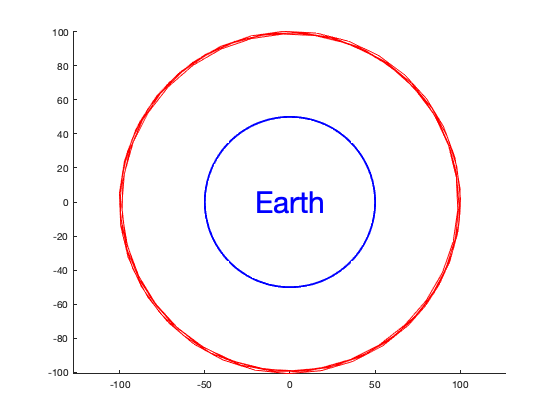

[T, D] = ode45(@rate_func, [0, 100], [100, 0, 0, -31.5], odeset('Events', @event_func));
clf; axis equal; hold on;
plot(D(:, 1), D(:, 2), "r")
%plot(T, D(:, 1), "r");
%plot(T, D(:, 2), "b--");
%plot(T, D(:, 3), "");
%plot(T, D(:, 4), "--");
viscircles([0 0], 50, 'Color', 'blue');
text(0, 0, "Earth", "HorizontalAlignment","center", "VerticalAlignment","middle", "Color", "blue", "FontSize", 30)
hold off; 

function [value, is_terminal, direction] = event_func(~, vals)
    [x, y, vx, vy] = matsplit(vals);
    
    value = max(abs([x, y])) - 50;
    direction = -1;
    is_terminal = 1;
end

function res = rate_func(~, vals)
    [x, y, vx, vy] = matsplit(vals);
    
    dxdt = vx;
    dydt = vy;
    
    v_vector = [x y];
    
    direction = v_vector / norm(v_vector); % TODO: -9.8 needs to change
    
    a_vector = -9.8 * direction;
    
    res = [dxdt; dydt; a_vector'];
end